# Multivariate scattered interpolation

*© *Copyright 2022 The MathWorks, In

## Halton dataset

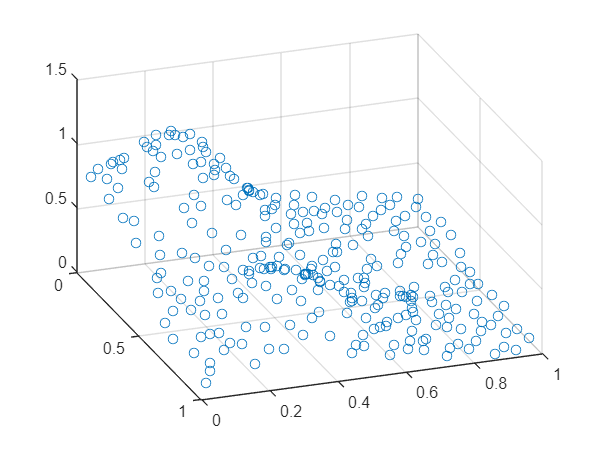

d = 2;                                              % d = space dimension
N = (2^4+1)^2;                                      % N = number of scattered points in R^d

% Generate quasi - random Halton set (see MATLAB Doc for Skip and Leap properties )
p = haltonset (d,'Skip' ,1e3 ,'Leap' ,1e2 );        % define quasi - random object in d- dim
p = p.scramble ('RR2');                             % use scramble method ( reverse - radix )
X = p.net (N);                                      % use net method to generate N points in R^d
F = franke(X(:,1), X(:,2));                                      % compute Franke 's test function

scatter3(X(:,1) ,X(:,2) ,F)
view ([70 35])

## RBF interpolator

dist_name = 'Euclidean';                         % choose a distance (>> doc pdist)
phi = @(r) r .^3;                                % choose an RBF

D = squareform(pdist(X, dist_name))              % 1) compute pairwise distances NxN

D =          0    0.7232    0.2134    0.8212    0.6811    0.5298    0.4105    0.9412    0.2103    0.5917    0.4676    0.9018    0.1309    0.7830    0.4588    0.7317    0.5400    0.6487    0.1742    0.9363    0.1437    0.4917    0.6832    0.8555    0.2428    0.7237    0.3314    0.8506    0.4407    0.5138    0.4132    0.9659    0.3154    0.6903    0.6049    0.8571    0.1276    0.5492    0.3331    0.7427    0.6535    0.6219    0.3494    1.0341    0.1699    0.4980    0.5742    0.7179    0.1581    0.8725
    0.7232         0    0.5300    0.5365    0.5231    0.1936    0.7554    0.2278    0.6899    0.4401    0.3372    0.3924    0.7572    0.2609    0.2657    0.6124    0.6018    0.2506    0.6435    0.2182    0.5807    0.6045    0.3513    0.1818    0.9213    0.0940    0.4025    0.4532    0.5115    0.3731    0.5455    0.3019    0.6350    0.6983    0.4398    0.3105    0.6287    0.1942    0.4042    0.5479    0.6901    0.1427    0.6967    0.3136    0.6076    0.4903    0.2634    0.3383    0.8102    0

A = phi(D)                                       % 2) apply RBF to distances

A =          0    0.3782    0.0097    0.5539    0.3159    0.1487    0.0692    0.8338    0.0093    0.2072    0.1023    0.7333    0.0022    0.4800    0.0966    0.3918    0.1575    0.2730    0.0053    0.8207    0.0030    0.1189    0.3189    0.6262    0.0143    0.3791    0.0364    0.6153    0.0856    0.1356    0.0706    0.9012    0.0314    0.3289    0.2213    0.6295    0.0021    0.1657    0.0370    0.4097    0.2791    0.2405    0.0427    1.1057    0.0049    0.1235    0.1893    0.3700    0.0040    0.6642
    0.3782         0    0.1489    0.1544    0.1431    0.0073    0.4310    0.0118    0.3283    0.0852    0.0384    0.0604    0.4341    0.0178    0.0188    0.2297    0.2180    0.0157    0.2665    0.0104    0.1958    0.2209    0.0433    0.0060    0.7819    0.0008    0.0652    0.0931    0.1338    0.0520    0.1624    0.0275    0.2560    0.3405    0.0851    0.0299    0.2485    0.0073    0.0660    0.1645    0.3286    0.0029    0.3382    0.0308    0.2243    0.1179    0.0183    0.0387    0.5319    0

lambda = A\F                                     % 3) solve linear system A* lambda = F

lambda =    -1.9865
   -0.6718
   -7.0520
    3.0418
  -22.9700
   -0.9012
  -10.3285
   -3.2625
   -2.4465
   -3.2667
